I = imread("img\bob.JPG")


I_r = zeros(size(I,1),size(I,2),size(I,3));
I_r(:,:,1) = I(:,:,1);
I_g = zeros(size(I,1),size(I,2),size(I,3));
I_g(:,:,2) = I(:,:,2);
I_b = zeros(size(I,1),size(I,2),size(I,3));
I_b(:,:,3) = I(:,:,3);



imshow(I)
imshow(I_r/255)%Red
imshow(I_g/255)%Gree
imshow(I_b/255)%Blue


threshold = 0.5;
I_r_thres = 1.*(I_r/255>threshold);
imshow((I_r_thres))%Red
imshow((I_r_thres(:,:,1)))%Red(B/W)
I_g_thres = 1.*(I_g/255>threshold);
imshow((I_g_thres))%Green
imshow((I_g_thres(:,:,2)))%Green(B/W)
I_b_thres = 1.*(I_b/255>threshold);
imshow((I_b_thres))%Blue
imshow((I_b_thres(:,:,3)))%Blue(B/W)
imshow(I_r_thres + I_b_thres + I_g_thres)

imshow(maskedRGBImage(:,:,1))
I_n = I;
 
mask_p = uint8(maskedRGBImage(:,:,2) >= 50);
mask_n = uint8(maskedRGBImage(:,:,2) < 50);

I_n = I_n.*mask_n;
for i = 1:3
    I_n(:,:,mod(i,3)+1) = I_n(:,:,mod(i,3)+1) + maskedRGBImage(:,:,mod(i-1,3)+1).*mask_p;
end
imshow(I_n)


C = imread("img\calendar_speckle10.jpg");
C = im2double(C);
imshow(C)


s = fspecial("sobel");
g = fspecial("gaussian");
tic
for i = 1:1000
    A = conv2(conv2(C,s),g);
end
toc
tic
for i = 1:1000
    B = conv2(C,conv2(s,g));
end
toc
imshow(A)
imshow(B)

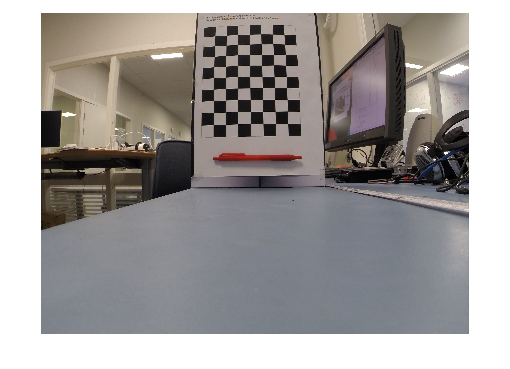

Pen1 = imread("img\pen1.JPG");
Pen2 = imread("img\pen2.JPG");
imshow(Pen1)

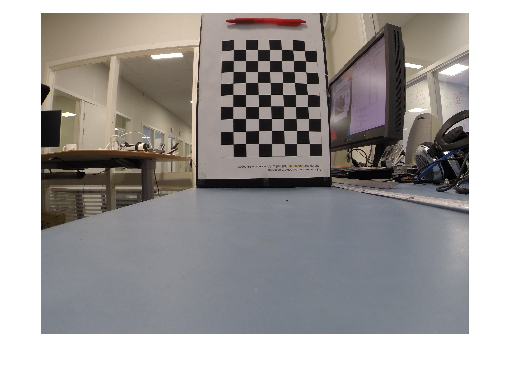

imshow(Pen2)


Pen1_len = 1563 - 1031

Pen1_len = 532

Pen2_len = 1588 - 1105

Pen2_len = 483

square_size1 = (1556 - 960)/8

square_size1 = 74.5000

square_size2 = (1642 - 1086)/8

square_size2 = 69.5000


pixelSize1 = 20/square_size1

pixelSize1 = 0.2685

pixelSize2 = 20/square_size2

pixelSize2 = 0.2878


distorted_pen1_len = Pen1_len*pixelSize1

distorted_pen1_len = 142.8188

distorted_pen2_len = Pen2_len*pixelSize2

distorted_pen2_len = 138.9928


f = cameraParams.Intrinsics.FocalLength(1); %Gained from the camera calibrator app

z1 = f*pixelSize1*140/distorted_pen1_len % Function derived from pinhole approximation slide h'/h = f/z 

z1 = 387.3688

z2 = f*pixelSize2*140/distorted_pen2_len

z2 = 426.6671

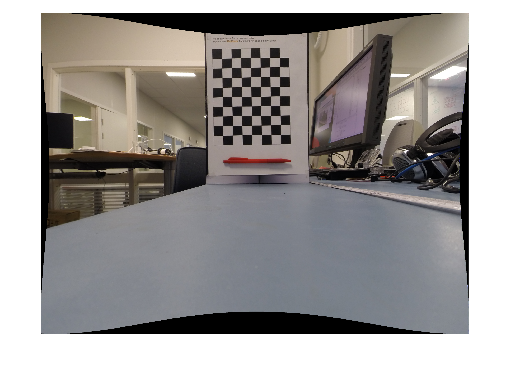


imshow(undistortImage(Pen1,cameraParams,'OutputView','full'))

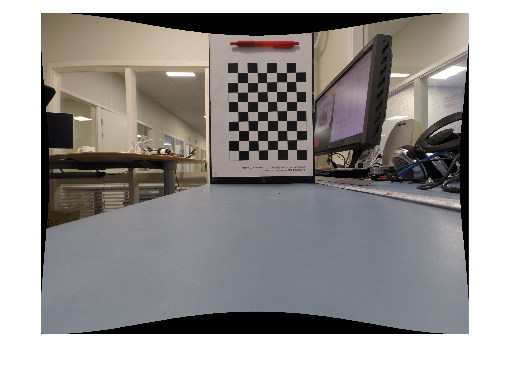

imshow(undistortImage(Pen2,cameraParams,'OutputView','full'))

Pen1_len = 2178 - 1643

Pen1_len = 535

Pen2_len = 2237 - 1692

Pen2_len = 545


square_size3 = (2169 - 1565)/8

square_size3 = 75.5000

square_size4 = (2296 - 1683)/8

square_size4 = 76.6250


pixelSize3 = 20/square_size3

pixelSize3 = 0.2649

pixelSize4 = 20/square_size4

pixelSize4 = 0.2610


undistorted_pen1_len = 20*Pen1_len/square_size3

undistorted_pen1_len = 141.7219

undistorted_pen2_len = 20*Pen2_len/square_size4

undistorted_pen2_len = 142.2512



z3 = f*pixelSize3*140/undistorted_pen1_len

z3 = 385.1966

z4 = f*pixelSize4*140/undistorted_pen2_len

z4 = 378.1288